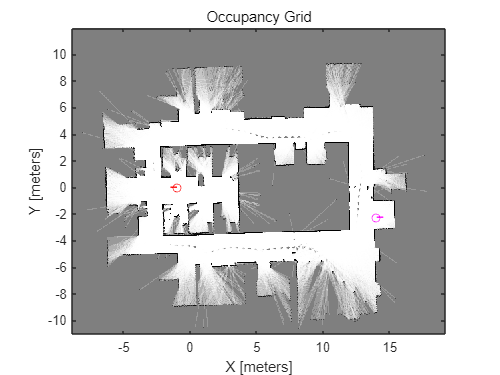

load("office_area_gridmap.mat","occGrid")
show(occGrid)

% Set start and goal poses.
start = [-1.0,0.0,-pi];
goal = [14,-2.25,0];

% Show start and goal positions of robot.
hold on
plot(start(1),start(2),'ro')
plot(goal(1),goal(2),'mo')

% Show start and goal headings.
r = 0.5;
plot([start(1),start(1) + r*cos(start(3))],[start(2),start(2) + r*sin(start(3))],'r-')
plot([goal(1),goal(1) + r*cos(goal(3))],[goal(2),goal(2) + r*sin(goal(3))],'m-')
hold off

bounds = [occGrid.XWorldLimits; occGrid.YWorldLimits; [-pi pi]];

ss = stateSpaceDubins(bounds);
ss.MinTurningRadius = 0.4;

stateValidator = validatorOccupancyMap(ss); 
stateValidator.Map = occGrid;
stateValidator.ValidationDistance = 0.05;

planner = plannerRRT(ss,stateValidator);
planner.MaxConnectionDistance = 2.0;
planner.MaxIterations = 30000;

planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

rng default

[pthObj, solnInfo] = plan(planner,start,goal);

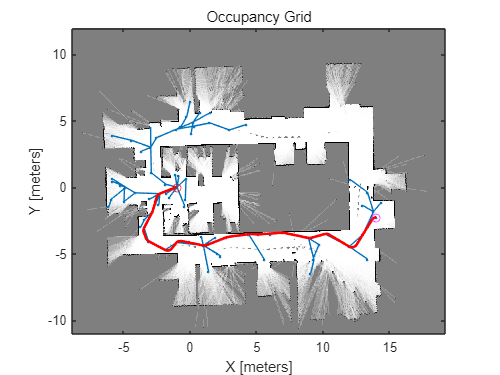

show(occGrid)
hold on

% Plot entire search tree.
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-');

% Interpolate and plot path.
interpolate(pthObj,300)
plot(pthObj.States(:,1),pthObj.States(:,2),'r-','LineWidth',2)

% Show start and goal in grid map.
plot(start(1),start(2),'ro')
plot(goal(1),goal(2),'mo')
hold off